# DC servomotor parameters (inertial load case)

clear all
clc

% Contains the set of all paramters given of the datasheet
% The last parts includes parameters evaluated for the control

### General parameters and conversion gains

%   conversion gains
rpm2rads = 2*pi/60;                 %   [rpm]   -> [rad/s]
rads2rpm = 60/2/pi;                 %   [rad/s] -> [rpm]

rpm2degs = 360/60;                  %   [rpm]   -> [deg/s]
degs2rpm = 60/360;                  %   [deg/s] -> [rpm]

deg2rad = pi/180;                   %   [deg]   -> [rad]
rad2deg = 180/pi;                   %   [rad]   -> [deg]

ozin2Nm = 0.706e-2;                 %   [oz*inch] -> [N*m]

### DC motor nominal parameters

%   brushed DC-motor Faulhaber 2338S006S
mot.R    = 2.6;                     %   armature resistance
mot.L    = 180e-6;                  %   armature inductance
mot.Kt   = 1.088 * ozin2Nm;         %   torque constant
mot.Ke   = 0.804e-3 * rads2rpm;     %   back-EMF constant
mot.J    = 5.523e-5 * ozin2Nm;      %   rotor inertia
mot.B    = 0.0;                     %   viscous friction coeff (n.a.)      
mot.eta  = 0.69;                    %   motor efficiency
mot.PN   = 3.23/mot.eta;            %   nominal output power
mot.UN   = 6;                       %   nominal voltage
mot.IN   = mot.PN/mot.UN;           %   nominal current
mot.tauN = mot.Kt*mot.IN;           %   nominal torque
mot.taus = 2.42 * ozin2Nm;          %   stall torque
mot.w0   = 7200 * rpm2rads;         %   no-load speed

### Gearbox nominal parameters

%   planetary gearbox Micromotor SA 23/1 
gbox.N1   = 14;                     %   1st reduction ratio (planetary gearbox)
gbox.eta1 = 0.80;                   %   gearbox efficiency 

%   external transmission gears
gbox.N2   = 1;                      %   2nd reduction ratio (external trasmission gears)
gbox.J72  = 1.4e-6;                 %   inertia of a single external 72 tooth gear      
gbox.eta2 = 1;                      %   external trasmission efficiency (n.a.)

%   overall gearbox data
gbox.N   = gbox.N1*gbox.N2;         %   total reduction ratio
gbox.eta = gbox.eta1*gbox.eta2;     %   total efficiency
gbox.J   = 3*gbox.J72;              %   total inertia (at gearbox output)

### Mechanical load nominal parameters

%   inertia disc params
mld.JD = 3e-5;                      %   load disc inertia
mld.BD = 0.0;                       %   load viscous coeff (n.a.)               

%   overall mech load params
mld.J     = mld.JD + gbox.J;        %   total inertia
mld.B     = 2e-6;                   %   total viscous fric coeff (estimated) 
mld.tausf = 1.0e-2;                 %   total static friction (estimated) 



### Voltage driver nominal parameters

%   op-amp circuit params
drv.R1 = 7.5e3;                     %   op-amp input resistor (dac to non-inverting in)
drv.R2 = 1.6e3;                     %   op-amp input resistor (non-inverting in to gnd)
drv.R3 = 1.2e3;                     %   op-amp feedback resistor (output to  inverting in)
drv.R4 = 0.5e3;                     %   op-amp feedback resistor (inverting in to gnd)
drv.C1 = 100e-9;                    %   op-amp input capacitor
drv.outmax = 12;                    %   op-amp max output voltage

%   voltage driver dc-gain      
drv.dcgain = drv.R2/(drv.R1+drv.R2) * (1 + drv.R3/drv.R4);

%   voltage driver time constant
drv.Tc = drv.C1 * drv.R1*drv.R2/(drv.R1+drv.R2);



### Sensors data

%   shunt resistor
sens.curr.Rs = 0.5;   

%   Hewlett-Packard HEDS-5540#A06 optical encoder
sens.enc.ppr = 500*4;                               %   pulses per rotation
sens.enc.pulse2deg = 360/sens.enc.ppr;              %   [pulses] -> [deg]
sens.enc.pulse2rad = 2*pi/sens.enc.ppr;             %   [pulses] -> [rad]
sens.enc.deg2pulse = sens.enc.ppr/360;              %   [deg] -> [pulses]
sens.enc.rad2pulse = sens.enc.ppr/2/pi;             %   [rad] -> [pulses]

%   potentiometer 1 (Spectrol 138-0-0-103) - installed on motor box
sens.pot1.range.R      = 10e3;                                          %   ohmic value range 
sens.pot1.range.V      = 5;                                             %   voltage range
sens.pot1.range.th_deg = 345;                                           %   angle range [deg]
sens.pot1.range.th     = sens.pot1.range.th_deg * deg2rad;              %   angle range [rad]                 
sens.pot1.deg2V        = sens.pot1.range.V / sens.pot1.range.th_deg;    %   sensitivity [V/deg]
sens.pot1.rad2V        = sens.pot1.range.V / sens.pot1.range.th;        %   sensitivity [V/rad]
sens.pot1.V2deg        = 1/sens.pot1.deg2V;                             %   conversion gain [V] -> [deg]
sens.pot1.V2rad        = 1/sens.pot1.rad2V;                             %   conversion gain [V] -> [rad]

### Data acquisition board (daq) data

%   NI PCI-6221 DAC data
daq.dac.bits = 16;                                  %   resolution (bits)
daq.dac.fs   = 10;                                  %   full scale 
daq.dac.q    = 2*daq.dac.fs/(2^daq.dac.bits-1);     %	quantization

%   NI PCI-6221 ADC data
daq.adc.bits = 16;                                  %   resolution (bits)
daq.adc.fs   = 10;                                  %   full scale (as set in SLDRT Analog Input block)
daq.adc.q    = 2*daq.adc.fs/(2^daq.adc.bits-1);     %   quantization 


### Sampling time

Ts = 1e-3;

### PID initialiazation

pid.Ki = 1;
pid.Kd = 1;
pid.K = 1;

### Required performances

perf.ts5 = 0.15;
perf.mp = 0.1;

perf.d = log(1/perf.mp)/sqrt(pi^2+log(1/perf.mp)^2);
perf.wg = 3/(perf.d*perf.ts5);
perf.phi = 100*perf.d;              %[deg] approximation for phi<70 deg
%perf.phi2=atan((2*perf.d)/(sqrt(sqrt(1+a*perf.d^4)-2*perf.d^2)));   %[rad] value not approximated

### Real derivative (2nd order, motor speed)

der.f = 20;
der.wc = 2*pi*der.f;
der.d = 1/sqrt(2);

### Real derivative (1st order, high pass)

der.b = 5;     % This parameter varies from 2 to 5, has to be set
der.Tl = 1/(der.b*perf.wg);

#### **Parameters ****estimated**** for the real motor in the lab**

real.Jeq = 6.73e-7;
real.Beq = 1.95e-6;
real.tausf = 6.2e-3; 

Find PID coefficients following the given instructions in frequency domain 

clear P

paramP.Jeq = real.Jeq;
paramP.Beq = real.Beq;

%P.Jeq = mot.J+mld.J/gbox.N^2;
%P.Beq = mot.B+mld.B/gbox.N^2;

% Define transfer function
paramP.Req = mot.R + sens.curr.Rs;
paramP.km = mot.Kt*drv.dcgain/(paramP.Req*paramP.Beq+mot.Kt*mot.Ke);
paramP.Tm = paramP.Req*paramP.Jeq/(paramP.Req*paramP.Beq+mot.Kt*mot.Ke);

s = tf('s');
P = paramP.km/(gbox.N*s*(paramP.Tm*s+1))

P =
 
        70.62
  -----------------
  0.4492 s^2 + 14 s
 
Continuous-time transfer function.



% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(P, perf.wg)

magPwg = 0.1010

phasePwg = -137.3500

dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;


% Estimation of the paramters of the PID controller
a = 320;                      % First attempt 4000
pid.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid)         

    Ki: 3.2823
    Kd: 0.0858
     K: 9.4929



**Initialize parameters to launch the simulation with ref deg **

simul.select1 = 3;      % {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % {1, 2, 3} = {step, stair, ramp}
simul.filtselect = 2;   % {1,2} = {discrete time, continuous time}
simul.stair_gain = 1;   % {-1, 1}
simul.ramp_gain = 1;    % [0,1]
simul.stepdeg = 360;    % sets the step amplitude of the deg step

**Anti-windup parameters**

awu.a = 5;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

#### Derivative for State-Space (different gains from before)

der.fSS = 50;
der.wcSS = 2*pi*der.fSS;
der.dSS = 1/sqrt(2);

#### State-Space Model of Plant

% Model used in Handout (CCF realization of simplified plant model)
ssP.A = [0, 1; 0 -1/paramP.Tm];
ssP.B = [0; paramP.km/(gbox.N*paramP.Tm)];
ssP.C = [1 0];
ssP.D = 0;

% ssP = ss(ssP.A,ssP.B,ssP.C,ssP.D); % Reach and Obs

#### Nominal Tracking

perf.sigmamin = 3/perf.ts5; % Pole minumum distance from imag axis (> 20)
perf.thetamax = acos(perf.d); % Pole maximum angle (rad) from real axis (< 54 degrees)

%%% Place Poles

% Eigenvalues of A are 0 and -1/Tm (-31). Move 0 eigenvalue to
% performance specification, leave stable pole as is.

ssNominal.K = place(ssP.A, ssP.B, [-perf.sigmamin ,-1/paramP.Tm]); % sets poles of A-BK

%%% Calculate nominal Gains
% Matrix should be invertible, as no zero for s=0 and reach and obs. (check Grim)
ssNominal.N = [ssP.A ssP.B; ssP.C ssP.D]\[zeros(2,1); 1]

ssNominal = struct with fields:
    K: [3.9647 0.1272]
    N: [3×1 double]


ssNominal.Nx = ssNominal.N(1:2);
ssNominal.Nu = ssNominal.N(3);
ssP.C*ssNominal.Nx % C*Nx == 1? (sanity check)

ans = 1

#### Robust Tracking (add Integral gain)

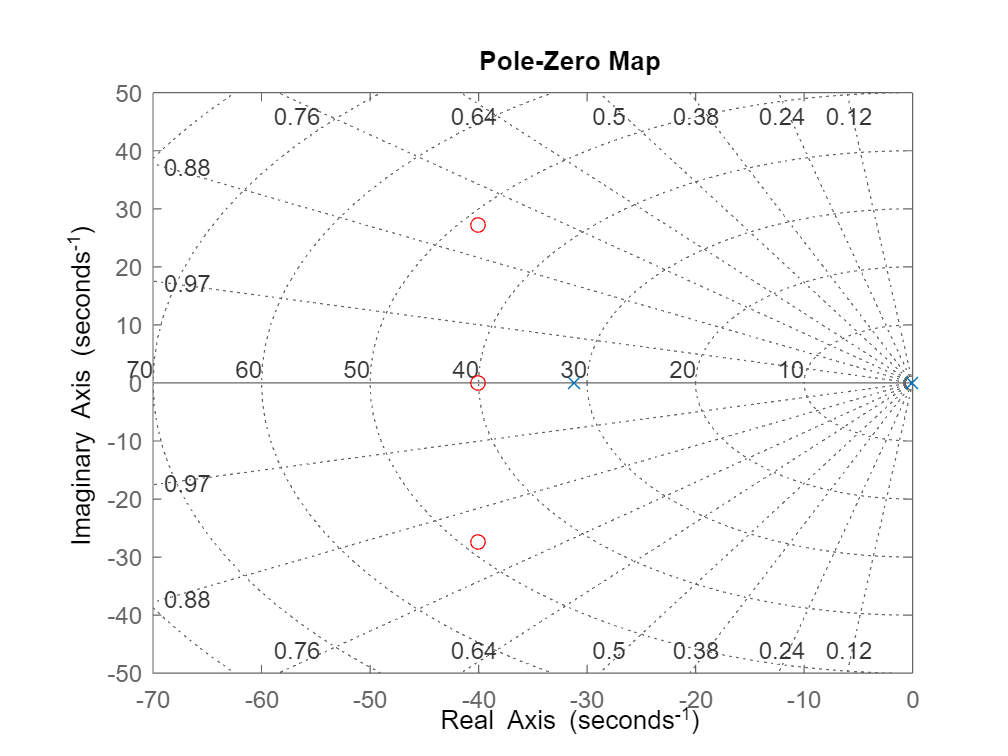

ans = 1.0e+06 *

    5.3271    0.0679    0.0081    0.0002    0.0000


ssP.Ae = [0, ssP.C; zeros(2,1), ssP.A];
ssP.Be = [0; ssP.B];

%%% Set Poles
% I assume with sigma in assignment we mean minimum necessary 
perf.wdmax = perf.sigmamin/perf.d * sqrt(1-perf.d^2);

% Pole sets to test from 2.2.3
ssRobust.poles1 = [-perf.sigmamin + 1i*perf.wdmax, -perf.sigmamin - 1i*perf.wdmax, -perf.sigmamin];
ssRobust.poles2 = [-perf.sigmamin, -perf.sigmamin, -perf.sigmamin];
ssRobust.poles3 = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];
ssRobust.poles4 = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -3*perf.sigmamin];
ssRobust.poles5= [-1000, -1000+30*1i, -1000-30*1i];

% Prepare different gains for Assignment 2.2.3
ssRobust.Ke1 = place(ssP.Ae, ssP.Be, ssRobust.poles1);
ssRobust.Ke2 = acker(ssP.Ae, ssP.Be, ssRobust.poles2); % use acker as we have pole multiplicity
ssRobust.Ke3 = place(ssP.Ae, ssP.Be, ssRobust.poles3);
ssRobust.Ke4 = place(ssP.Ae, ssP.Be, ssRobust.poles4);
ssRobust.Ke5 = place(ssP.Ae, ssP.Be, ssRobust.poles5);

ssRobust.Ki1 = ssRobust.Ke1(1);
ssRobust.K1 = ssRobust.Ke1(2:3);

ssRobust.Ki2 = ssRobust.Ke2(1);
ssRobust.K2 = ssRobust.Ke2(2:3);

ssRobust.Ki3 = ssRobust.Ke3(1);
ssRobust.K3 = ssRobust.Ke3(2:3);

ssRobust.Ki4 = ssRobust.Ke4(1);
ssRobust.K4 = ssRobust.Ke4(2:3);

ssRobust.Ki5 = ssRobust.Ke5(1);
ssRobust.K5 = ssRobust.Ke5(2:3);

% Variable used in the Simulation you just need to assign the configuration
% you want in the automated_simulation.slx
ssRobust.Ki = ssRobust.Ki1;
ssRobust.K = ssRobust.K1;

pzmap(P)
grid on
hold on
plot(ssRobust.poles3, 'o','Color','red')
plot(ssRobust.poles5, 'o','Color','blue')
xlim([-70 0])
ylim([-50 50])

#### Extended Estimator Approach

% Does the same task as error space, with different method.
% I will reuse reference signals used for error space above.

%%% Disturbance+Reference model (same signal model as for error space/in handout)
ssEstimator.A_rho = ssError.Ar;
ssEstimator.C_rho = [1 0 0]; % (A_rho, C_rho) obs
% Here we assume EV's of the reference signal are not zeros of the plant (our plant has no zeros)

%%% Extended plant model (including reference, plant and disturbance)
%%% Input: u, Output: e = y - r
ssEstimator.Ae = [ssEstimator.A_rho, zeros(3,2); ssP.B*ssEstimator.C_rho, ssP.A];
ssEstimator.Be = [zeros(3,1); ssP.B];
ssEstimator.Ce = [zeros(1,3), ssP.C];

%%% Design Estimator for Extended Plant Model (choose poles: TUNING)
% ssEstimator.obspoles = 2*perf.wnmin*[exp(1i*(-1+1/3)*pi) exp(1i*(-1-1/3)*pi) exp(1i*(-1+1/6)*pi) exp(1i*(-1-1/6)*pi) -1];
ssEstimator.obspoles = 2*perf.wnmin*[-0.5000-0.8660i  -0.5000+0.8660i  -0.8660-0.5000i  -0.8660+0.5000i  -1.0000];
ssEstimator.ctrlpoles = [-perf.sigmamin - 1i*perf.wdmax, -perf.sigmamin + 1i*perf.wdmax]; 

ssEstimator.K = place(ssP.A, ssP.B, ssEstimator.ctrlpoles);
ssEstimator.K

ans =     7.2807    0.0562


ssEstimator.Le = (place(ssEstimator.Ae', ssEstimator.Ce', ssEstimator.obspoles))'; % notice the last transpose
ssEstimator.Le

ans = 1.0e+06 *

    0.0099
    0.1869
   -8.3825
    0.0002
    0.0209


% (A,C) and (A_rho,C_rho) are obs and plant has no zeros => (Ae, Ce) is Obs

Save the used parameters to a file such that they can be used without running this every time

save('parameters.mat')